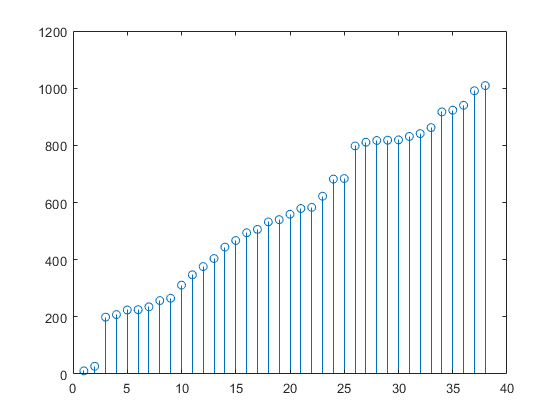

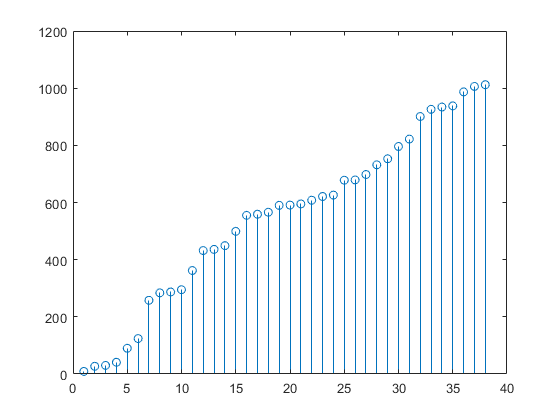

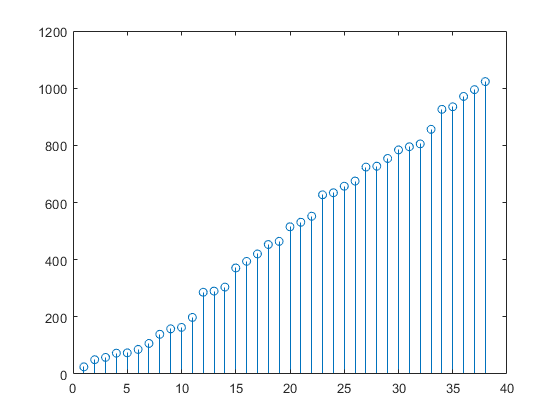

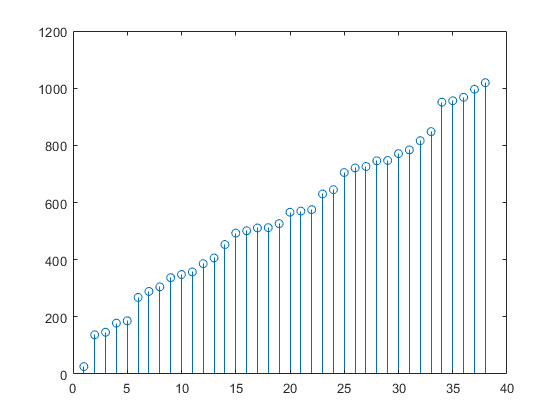

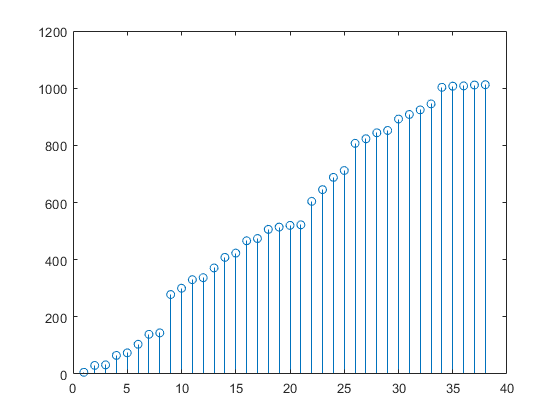

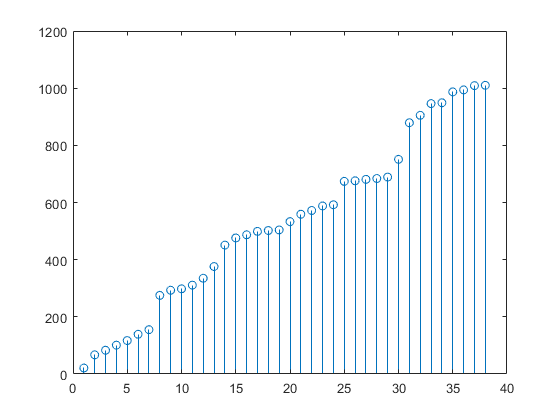

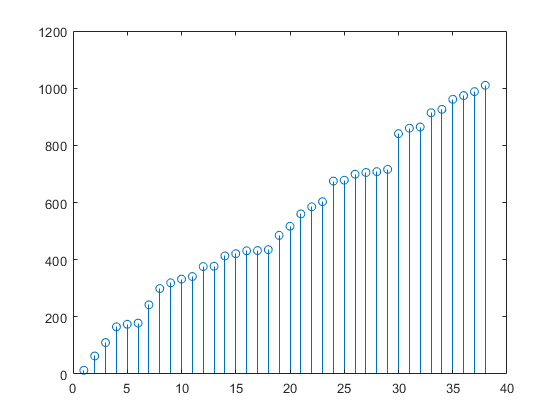

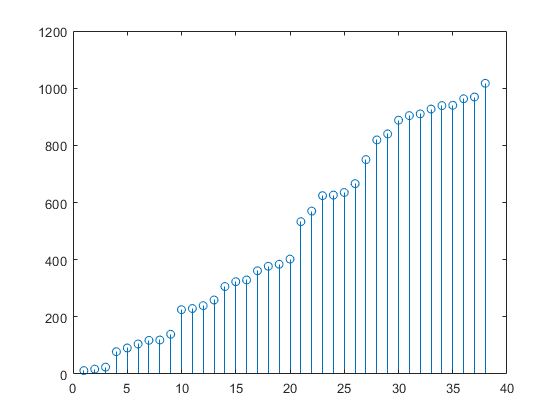

clear;clc;
% Example usage
n = 1024;  % Total number of bits
x_array = 38*ones(1,15);   % Number of ones
dataCols=[];
dataColsComp=[];
for x=x_array
    [random_array,random_array_comp,one_indices] = generate_random_array(n, x);
    figure();
    stem(one_indices);
    dataCols=[dataCols;[random_array,zeros(1,1092-1024)]];
    dataColsComp=[dataColsComp;[random_array_comp,zeros(1,1092-1024)]];
end

save("./SDCard_BinFiles/dataCols_4XRandomize.mat","dataCols","dataColsComp");
